# Computer Assignment 4 - Signals & Systems - Dr  Akhavan

### Question 0-1

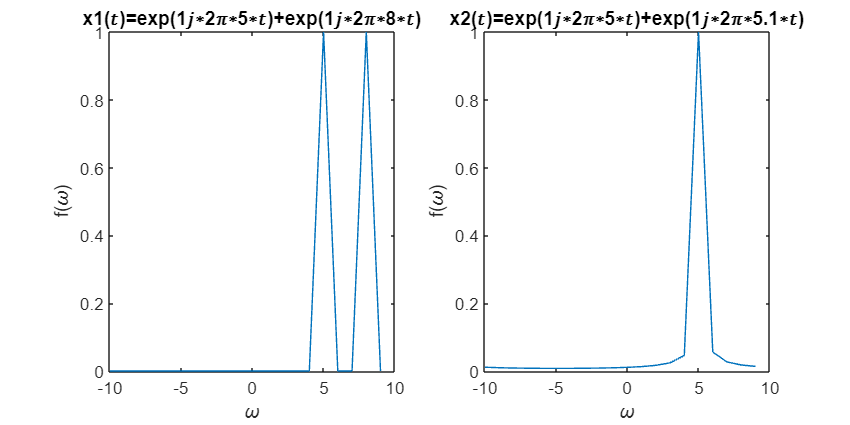

clc, clearvars, close all;
fs = 20;
t_start = 0;
t_end = 1;
ts = 1 / fs;
t = t_start:ts:t_end - ts;
T = t_end - t_start;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
x1 = exp(1j * 2 * pi * 5  * t) + exp(1j * 2 * pi * 8  * t);
x2 = exp(1j * 2 * pi * 5  * t) + exp(1j * 2 * pi * 5.1  * t);
figure('Position', [0,0,1000,500]);
y1 = fftshift(fft(x1));
y2 = fftshift(fft(x2));
subplot(1,2,1);
plot(f, abs(y1) / max(abs(y1)));
title("x1(𝑡)=exp(1𝑗∗2𝜋∗5∗𝑡)+exp(1𝑗∗2𝜋∗8∗𝑡)");
xlabel("\omega"); ylabel("f(\omega)")
subplot(1,2,2);
plot(f, abs(y2) / max(abs(y2)));
title("x2(𝑡)=exp(1𝑗∗2𝜋∗5∗𝑡)+exp(1𝑗∗2𝜋∗5.1∗𝑡)");
xlabel("\omega"); ylabel("f(\omega)")

### **Part 1**

clc, clearvars, close all;

#### **1 - 1)**

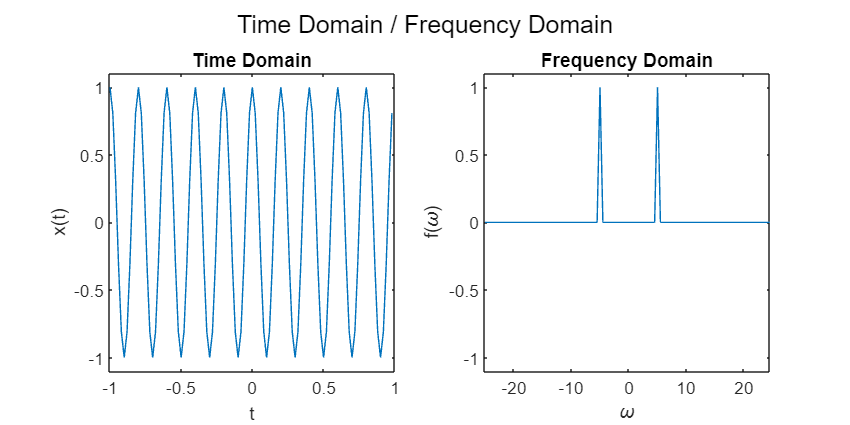

fs = 50;
t_start = -1;
t_end = 1;
ts = 1 / fs;
t = t_start:ts:t_end - ts;
T = t_end - t_start;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
x1 = cos(10 * pi * t);

figure('Position', [0,0,1000,500]);
sgtitle("Time Domain / Frequency Domain");
subplot(1,2,1)
plot(t, x1);
title ("Time Domain");
xlabel("t"); ylabel("x(t)");
ylim([-1.1,1.1])
y1 = fftshift(fft(x1));
y1 = y1 / max(abs(y1));

subplot(1,2,2)
plot(f, abs(y1));
ylim([-1.1,1.1])
title ("Frequency Domain");
xlabel("\omega"); ylabel("f(\omega)");

#### 1 - 2)

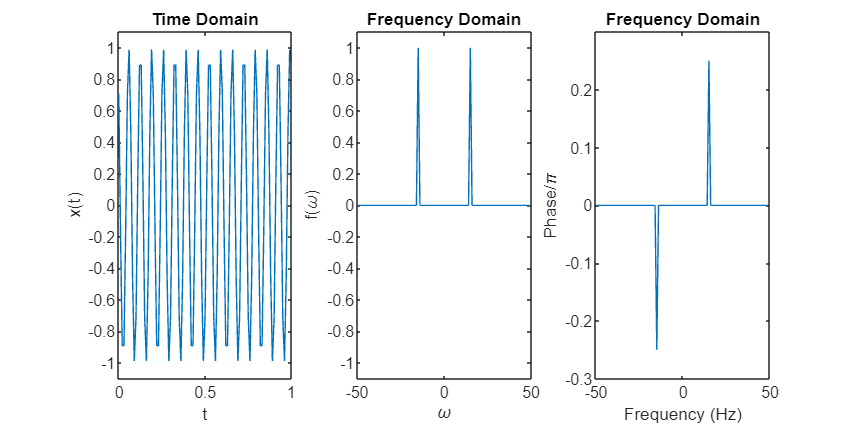

fs = 100;
t_start = 0;
t_end = 1;
ts = 1 / fs;
t = t_start:ts:t_end - ts;
T = t_end - t_start;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
x2 = cos(30 * pi * t + pi/4);
figure('Position', [0,0,1000,500]);
subplot(1,3,1)
plot(t, x2);
title ("Time Domain");
xlabel("t"); ylabel("x(t)");
ylim([-1.1,1.1])
y2 = fftshift(fft(x2));
y2 = y2 / max(abs(y2));
subplot(1,3,2)
plot(f, abs(y2));
title ("Frequency Domain");
xlabel("\omega"); ylabel("f(\omega)");
ylim([-1.1,1.1])
tol = 1e-6;
y2(abs(y2) < tol) = 0;
theta = angle(y2);
subplot(1,3,3)
plot(f, theta/pi);
title ("Frequency Domain");
xlabel("Frequency (Hz)"); ylabel("Phase/\pi");
ylim([-0.3,0.3])

### Part 2

clc, clearvars, close all;

#### 2 - 1) Creating mapset

Nch = 32; 
mapset = cell(2,Nch); 
Alphabet ='abcdefghijklmnopqrstuvwxyz .,!";'; 
for i = 1:Nch 
    mapset{1,i}=Alphabet(i); 
    mapset{2,i}=dec2bin(i-1,5); 
end

#### 2 - 2)

#### 2 - 3)

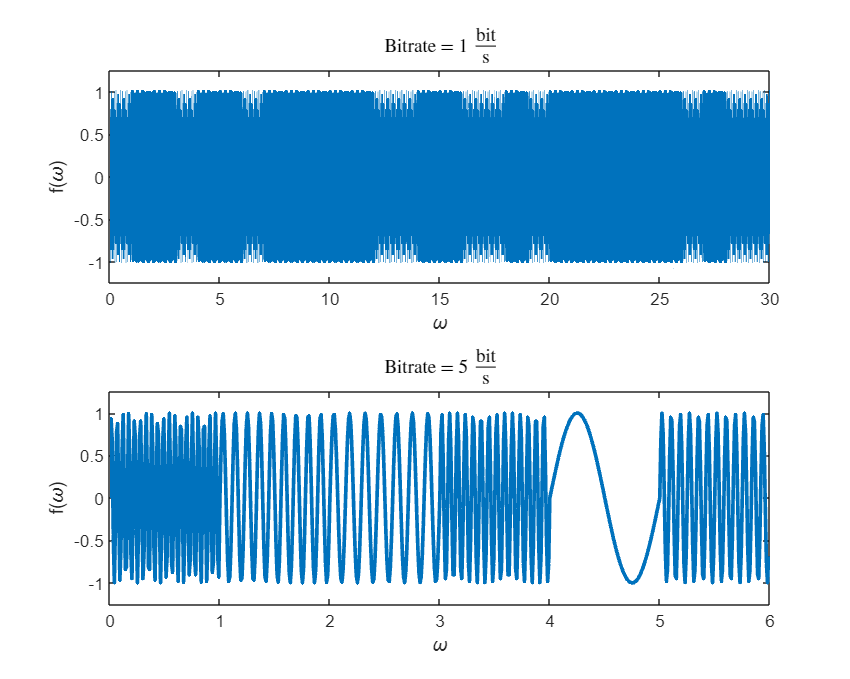

message = 'signal';
fs = 100;
ts = 1/fs;
bitrates = [1,5];
codedMessage = cell(1, 2);
figure('Position', [0,0,1000,800]);
for i = 1:2
    codedMessage{i} = coding_freq(message, bitrates(i), mapset);
    t = 0:(1/fs):(length(codedMessage{i})/fs)-(1/fs);
    subplot(2, 1, i);
    plot(t,codedMessage{i}, 'LineWidth', 2)
    title("Bitrate = " + bitrates(i) + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
    xlabel("\omega"); ylabel("f(\omega)");
    ylim([-1.25, 1.25]);
end

#### 2 - 4)

for i = 1:2
    decodedMessage = decoding_freq(codedMessage{i}, bitrates(i), mapset);
    fprintf ('Bitrate: %d Decoded Message: %s\n', bitrates(i), decodedMessage)
end

Bitrate: 1 Decoded Message: signal
Bitrate: 5 Decoded Message: signal


#### 2 - 5)

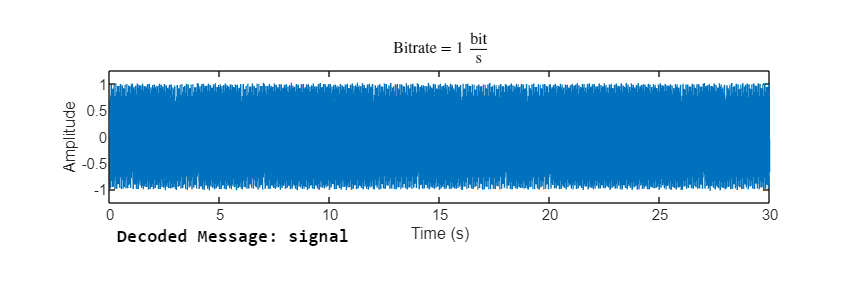

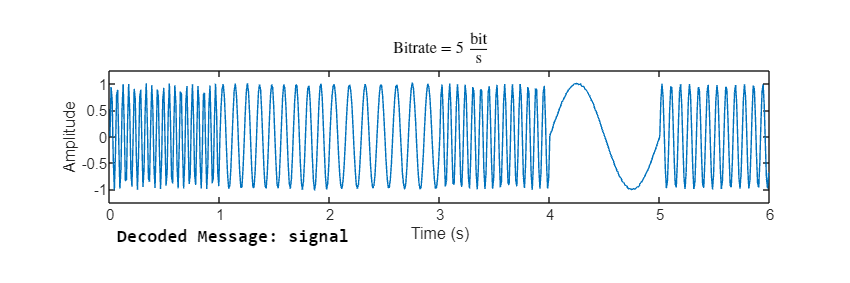

message = 'signal';
fs = 100;
std = 0.01;
codedMessage = cell(1,3);
noisyMessage = cell(1,3);

for i = 1:2
    codedMessage{i} = coding_freq(message, bitrates(i), mapset);
    noise = std * randn(1, length(codedMessage{i}));
    noisyMessage{i} = codedMessage{i} + noise;
    t = 0:1/fs:(length(noisyMessage{i})/fs) - 1/fs;
    figure('Position',[0,0,1500,500]);
    subplot(5,1,2:4)
    plot(t, noisyMessage{i})
    title("Bitrate = " + bitrates(i) + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
    xlabel("Time (s)")
    ylabel("Amplitude")
    ylim([-1.25, 1.25])
    decodedMessage = decoding_freq(noisyMessage{i}, bitrates(i), mapset);
    subplot(5,1,5)
    axis off
    text(0.01, 0.5, sprintf('Decoded Message: %s', decodedMessage), 'FontName','consolas', 'FontSize', 10, 'FontWeight','bold')
end

#### 2 - 6)

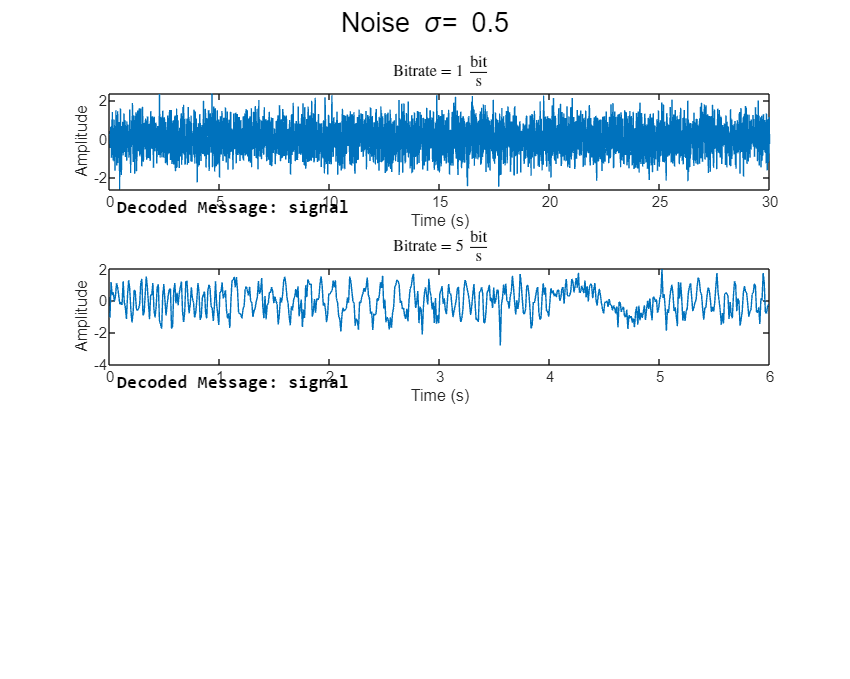

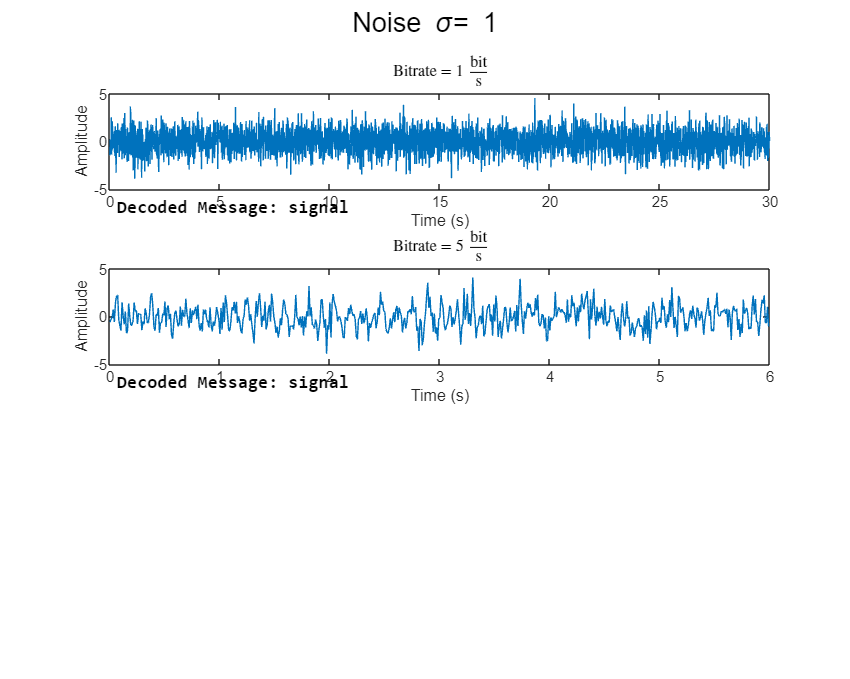

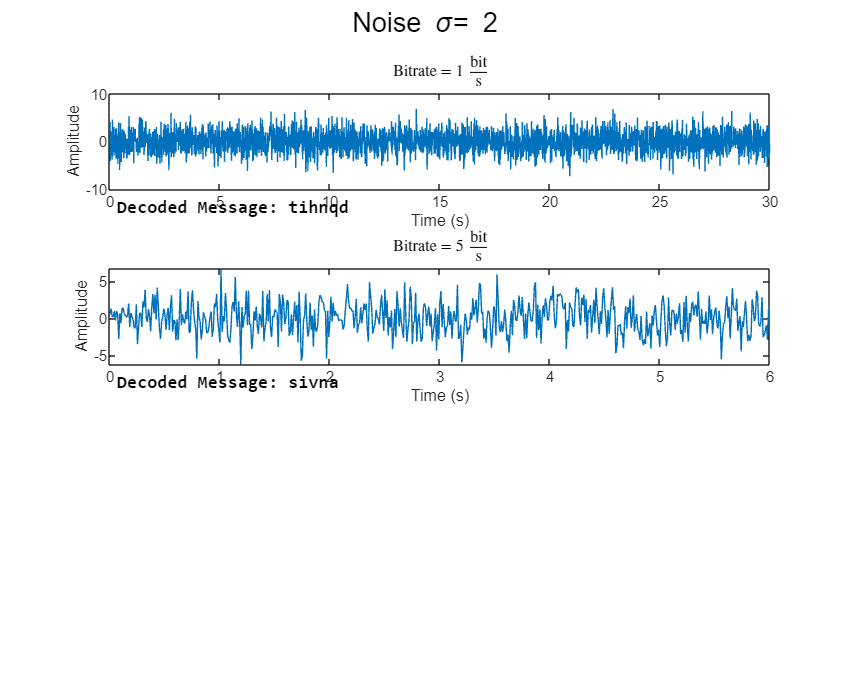

message = 'signal';
fs = 100;
codedMessage = cell(1,3);
noisyMessage = cell(1,3);
stds = [0.5, 1, 2];
for std = stds
    figure('Position',[0, 0, 1500, 1200]);
    sgtitle("Noise \sigma= " + std);
    for i = 1:2
        codedMessage{i} = coding_freq(message, bitrates(i), mapset);
        noise = std * randn(1, length(codedMessage{i}));
        noisyMessage{i} = codedMessage{i} + noise;
        t = 0:1/fs:(length(noisyMessage{i})/fs) - 1/fs;
        subplot(15,1,((i-1)*5 + 1):((i-1)*5 + 3));
        plot(t, noisyMessage{i})
        title("Bitrate = " + bitrates(i) + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
        xlabel("Time (s)"); ylabel("Amplitude");
        decodedMessage = decoding_freq(noisyMessage{i}, bitrates(i), mapset);
        subplot(15,1,(i-1)*5 + 4);
        axis off
        text(0.01, 0.5, sprintf('Decoded Message: %s', decodedMessage), 'FontName','consolas', 'FontSize', 10, FontWeight='bold')
    end
end

#### 2 - 7)

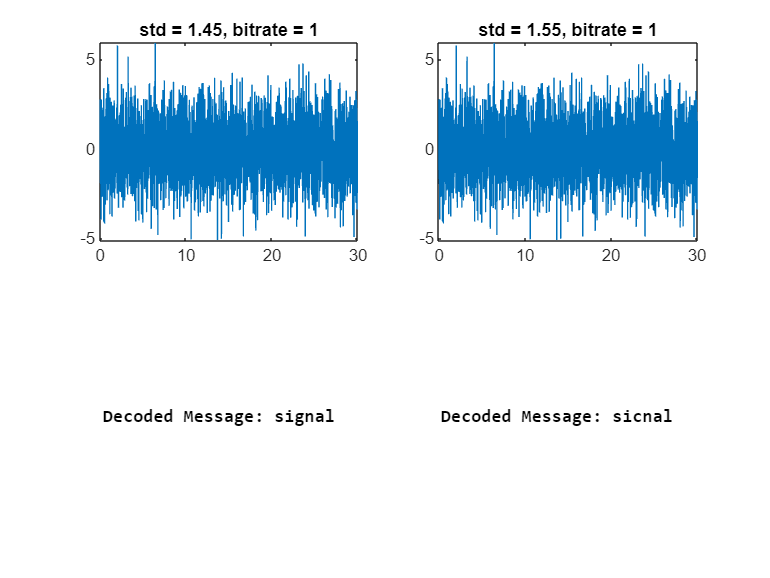

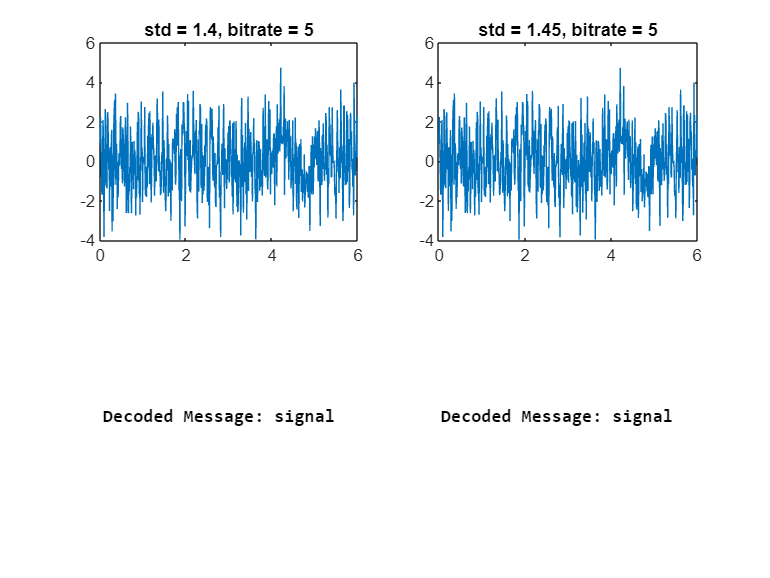

message = 'signal';
fs = 100;
codedMessage = cell(1,2);
stds = {[1.45, 1.55], [1.4,1.45]};
for i = 1:2
    codedMessage{i} = coding_freq(message, bitrates(i), mapset);
    std = stds{i};
    noise1 = std(1) * randn(1, length(codedMessage{i}));
    noise2 = std(2) * randn(1, length(codedMessage{i}));
    noisyMessage1 = codedMessage{i} + noise1;
    noisyMessage2 = codedMessage{i} + noise2;
    t = 0:1/fs:(length(codedMessage{i})/fs) - 1/fs;
    figure
    subplot(2,2,1);
    plot(t, noisyMessage1);
    title("std = " + std(1) + ", bitrate = " + bitrates(i));
    subplot(2,2,2);
    plot(t, noisyMessage1);
    title("std = " + std(2) + ", bitrate = " + bitrates(i));
    subplot(2,2,3);
    text(0.01, 0.5, sprintf('Decoded Message: %s', decoding_freq(noisyMessage1, bitrates(i), mapset)), 'FontName','consolas', 'FontSize', 10, FontWeight='bold')    
    axis off
    subplot(2,2,4);
    text(0.01, 0.5, sprintf('Decoded Message: %s', decoding_freq(noisyMessage2, bitrates(i), mapset)), 'FontName','consolas', 'FontSize', 10, FontWeight='bold')
    axis off
end

#### 2 - 8)

#### 2 - 9)

### Functions

function binarizedMessage = message2binary(message, mapset)
    binarizedMessage = '';
    for charInMessage = message
        found = false;
        for charInMapSet = mapset
            if charInMessage == charInMapSet{1};
                binarizedMessage = [binarizedMessage, charInMapSet{2}];
                found = true;
                break;
            end
        end
        if ~found
            fprintf('Character "%c" not found in mapset. Skipping...\n', charInMessage);
        end
    end
end

function codedMessage = coding_freq(message ,bitrate, mapset)
while(mod(length(message) * 5, bitrate) ~= 0)
    message = [message, ';'];
end
fs = 100;
ts = 1/fs;
t_start = 0; t_end = 1;
t = t_start:ts:t_end - ts;

fStep = floor((fs / 2) / 2 ^ bitrate);
fStart = ceil(fStep / 2);
codedMessage = [];
binarizedMessage = message2binary(message, mapset);
for i = 1:bitrate:length(binarizedMessage)
    bit = binarizedMessage(i: i+bitrate-1);
    f = fStart + fStep * bin2dec(bit); 
    signal = sin(2*pi*f*t);
    codedMessage = [codedMessage, signal];
end
end

function character = getCharacter(binary, mapset)
    for char = mapset
        if char{2} == binary
            character = char{1};
            break;
        end
    end 
end

function decodedMessage = decoding_freq(codedMessage, bitrate, mapset)
fs = 100;
fStep = floor((fs / 2) / 2 ^ bitrate);
fStart = ceil(fStep / 2);
binarizedMessage = '';
decodedMessage = '';
for i = 1:length(codedMessage)/fs
    segment = codedMessage((i-1) * fs + 1: i * fs);
    [~, maxF] = max(abs(fftshift(fft(segment))));
    maxF = abs(maxF - fs / 2 -1);
    for j = 0:(2^bitrate - 1)
        if (fStart + j * fStep - fStep/2) <= maxF && maxF <= (fStart + j * fStep + fStep/2)
            binarizedMessage = [binarizedMessage, dec2bin(j,bitrate)];
            break;
        end
    end
end
for i = 1:5:floor(length(binarizedMessage) /5) * 5
    character = getCharacter(binarizedMessage(i:i+4), mapset);
    decodedMessage = [decodedMessage, character];
end
end
